# Plot Syllable Acoustics

## Step 1: Quantify Acoustics

Quantify the acoustics of individual syllables. For each syllable, the calculated acoustics will be saved in the '*.not.mat' file.

bird = 'br177yw112';
syls ='d'% ['doae'];

syls = 'd'


for i = 1:length(syls)
    this_syll = syls(i);
    QuantPitchContours_leila(this_syll,1024,1020,1.0)
    quantify_acoustics(this_syll,1,'mat');
end    

Found 4 examples of 'd' in br173gr56_220910_081617_songbout1.mat.not.mat
  Columns 1 through 3

    {'Sampling freque…'}    {'click 'OK' to r…'}    {'otherwise click…'}

  Column 4

    {'to a different …'}



btn = 'OK'

Found 5 examples of 'd' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 3 examples of 'd' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 3 examples of 'd' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 3 examples of 'd' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 2 examples of 'd' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 1 examples of 'd' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 1 examples of 'd' in br173gr56_220910_082517_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220910_082617_songbout1.mat.not.mat
Found 2 examples of 'd' in br173gr56_220910_082717_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220910_082817_

% QUERY: BIRD 1
% bird = 'br177yw112';
% days = [62 66 68 73 86 88];

% syls = ['epqrs'];

% QUERY: BIRD 2
bird = 'br173gr56';
days = [78 801 802 803 811 812 153];
syls = ['pqrs'];

warning('on','all')
failedSyls ={};
for d= 1:length(days)
    day = days(d)
    [~,~,~,folder,~] = raster_params(bird,day);
    cd(folder)
    for i = 1:length(syls)
        try
        this_syll = syls(i)
        QuantPitchContours_leila(this_syll,1024,1020,1.0)
        quantify_acoustics(this_syll,1,'mat');

        catch exception
            message = ['failed for: ' num2str(day) ' -syl ' syls(i)];
            failedSyls = [failedSyls; message];
            display(message)
        end
    end
end

% INSPECT SYLLABLE QUANTIFICATIONS
%set the quantification parameters for this_syll
syllable_params_by_bird_leila(this_bird,this_syll);
one_syl_spectrogram_post_quant(this_syll,'manual'); % take params from syllable_params...
% repeat above steps until you're set on the proper syllable params
one_syl_spectrogram_post_quant(this_syll,'notmat'); %take params from notmat files

% QuantPitchContours(this_syl,NFFT,overlap,sigma)
QuantPitchContours_leila(this_syll,1024,1020,1.0)
OneSylSpecWithPitchContours_leila(this_syll,1)

% quantify syllable acoustics using the syllable params above. Results are
% saved in the '.not.mat' files. Summary table of results from all files on
% this directory are saved as '__birdname__date___syl_x.mat'
quantify_acoustics(this_syll,1,'mat');

## STEP 2: Plot Quantified Acoustics

## 3D Scatter Plot

clear all
syls = ['p']; 
day = [62 73 88];
bird = 'br177yw112';
x = 'amp_at_pitchquant'; y = 'spect_entropy'; z = 'peak_pinterp';
lbl_x = 'log10(Amplitude)'; lbl_y = 'Spectral Entropy'; lbl_z = 'Pitch';

% Convert syllables into unique scalar values for color coding
colors = syls -'a'+1;

% Load acoustics data and save a table for each day_syllable data
for d = 1:length(day)
    
    [~,~,~,folder,recdate] = raster_params(bird,day(d));
    cd(folder)

    for s=1:length(syls)
        try
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        eval(sprintf('day%d_%s = syl_sum;',day(d),syls(s)));
        end
    end
end

% Create 3d Scatterplots with Column = Day, Color = syllable category
f = figure; set(f, 'Visible', 'on')
tiledlayout(1,length(day));
textbox1 = annotation('textbox',[0 0 1 1],'String',...
[bird ' acoustics for syllables: ' syls],...
'fontsize',16,'HorizontalAlignment','center','VerticalAlignment','cap');

for d = 1:length(day)
    ax(d) = nexttile;
    t = title(['Day ' num2str(day(d))]);
    t.FontSize = 14;
    if exist(sprintf('day%d_%s;', day(d),syls(s)))
        
    
        for s = 1:length(syls)
            eval(sprintf('tbl = day%d_%s;', day(d),syls(s)));
            eval(sprintf('x1 = tbl.%s;',x));
            eval(sprintf('y1 = tbl.%s;',y));
            eval(sprintf('z1 = tbl.%s;',z));
            sylcolor = repmat(colors(s),length(x1),1);
            
            % If Amplitude, plot the log10 
            if contains(x,'amp') x1 = log10(x1);end
            if contains(y,'amp') y1 = log10(y1);end
            if contains(z,'amp') z1 = log10(z1);end
    
            scatter =scatter3(x1,y1,z1,[],sylcolor,"filled");
            scatter.SizeData = 20;
            hold on 
        end
    end
end
lgd = legend(syls(:),'FontSize',16,'Box','off');
lgd.Title.String = 'Syllable';
lgd.Title.FontSize = 16;
colormap("turbo")
xlabel(lbl_x); ylabel(lbl_y); zlabel(lbl_z)
hlink = linkprop(ax,{'CameraPosition','CameraUpVector','CameraTarget','View','CameraPositionMode',...
    'Xlim','Ylim','Zlim','PlotBoxAspectRatio'});
rotate3d on

## Scatter Plot Matrices - multiple syllables in one plot

clear all
syls = ['d']; 
day = [68 88]; % Run for one day at a time
bird = 'br177yw112';
numvars = 5; % how many variables are you plotting
varNames = {'Duration'; 'Amplitude (log)';'Spectral Entropy';'Pitch'; 'Wiener Entropy'};

% Plot Placements of X and Y variable Names - manually change when varying
% the number of variables plotted

x_lbl = [.08 .24 .43 .66 .83]; y_lbl = [.86 .62 .41 .25 .02]; % optimal for 5 vars


plotvar = strings(length(varNames),1);
for a = 1:length(varNames)
    if contains(varNames(a),'duration',"IgnoreCase",true)
        plotvar(a) = 'syl_dur';
        limits = [0 0.14];
    elseif contains(varNames(a),'amplitude',"IgnoreCase",true)
        plotvar(a) = 'amp_at_pitchquant';
        limits = [-8 0]
    elseif contains(varNames(a),'spectral',"IgnoreCase",true)
        plotvar(a) = 'spect_entropy';
        limits = [0.25 1.75]
    elseif contains(varNames(a),'pitch',"IgnoreCase",true)
        plotvar(a) = 'peak_pinterp';
        limits = [1500 3000]
    elseif contains(varNames(a), 'wiener',"IgnoreCase",true)
        plotvar(a) = 'wiener_entropy';
        limits = [-40 -5]
    end
end

limits =     -8     0


limits =     0.2500    1.7500


limits =         1500        3000


limits =    -40    -5



% Load acoustics data and save a table for each day_syllable data
for d = 1:length(day)
    [~,~,~,~,recdate] = raster_params(bird,day(d));
    
    eval(sprintf('day%d = table;',day(d)))
    for s=1:length(syls)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        eval(sprintf('day%d_%s = syl_sum;',day(d),syls(s)));
        eval(sprintf('temp = day%d_%s;', day(d),syls(s)))
        eval(sprintf('day%d = vertcat(day%d, day%d_%s);',day(d),day(d),day(d),syls(s)))
    end
    
    % Create vector of syllables for color labeling
    eval(sprintf("len%d = size(day%d,1); syls%d = cell2mat(day%d.syllable);",...
        day(d),day(d),day(d),day(d)));
    
    % Create array for plotting
    X = [];
    for b = 1:length(varNames)
        eval(sprintf('ac%d = day%d.%s;', b, day(d),plotvar(b)))
        if contains(plotvar(b),'amp')
            eval(sprintf('ac%d = log(day%d.%s);', b, day(d),plotvar(b)))
        end
        eval(sprintf('X = horzcat(X,ac%d);', b))
    end
    
    clr = turbo(length(syls));
    sizen = repmat(numvars,numvars,1); %assign size to first value

    % Plot Matrix for given day
    g(d) = figure; set(g(d), 'Visible', 'on')
    eval(sprintf('gplotmatrix(X,[],syls%d,clr,[],size,[])',day(d)));
    title(sprintf('%s - Acoustics for DAY %d', bird,(day(d))))
    text(x_lbl(1:numvars), repmat(-.1,1,numvars), varNames, 'FontSize',12);
    text(repmat(-.12,1,numvars), y_lbl(1:numvars), varNames, 'FontSize',12, 'Rotation',90);
end

Error using size
Not enough input arguments.

## Scatter Plot Matrices - 1 syllable, multiple days in one plot

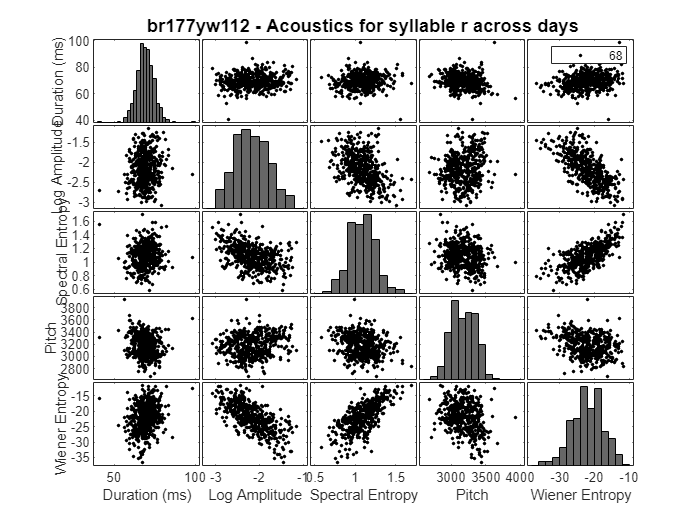

syls = ['c']; 
day = [68]; % Run for one day at a time
bird = 'br177yw112';
varNames = {'Duration (ms)', 'Log Amplitude','Spectral Entropy','Pitch', 'Wiener Entropy'};
numvars = length(varNames); % how many variables are you plotting

% Plot Placements of X and Y variable Names - manually change when varying
% the number of variables plotted
g = figure; set(g, 'Visible', 'on')
x_lbl = [.08 .24 .43 .66 .83]; y_lbl = [.86 .62 .41 .25 .02]; % optimal for 5 vars


% Data table that will store acoustics for all the days
allAcoustics = table;
allLabels = [];
for s = 1:length(syls)
    for d = 1:length(day)
    
        % load acoustic data for syllable for day(d) and store in allAcoustics
        [~,~,~,folder,recdate] = raster_params(bird,day(d));
        cd(folder)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        syl_sum.day = repmat(day(d),size(syl_sum,1),1);
        allAcoustics = vertcat(allAcoustics,syl_sum);
    
        % Create GROUP vector of syllables for color labeling
        if day(d) ==0
            label_day = repmat(char([num2str(day(d)) syls(s)]),size(syl_sum,1),1);
        elseif day(d) == 0
            label_day = repmat(char([num2str(day(d)) syls(s)]),size(syl_sum,1),1);
        else
            label_day = repmat([num2str(day(d)) ' '],size(syl_sum,1),1);
        end
        allLabels = vertcat(allLabels,label_day);
    end
end

% Designate X and Y Plots
plotvar = strings(length(varNames),1);
limits = [];
X = [];
for a = 1:length(varNames)
    if contains(varNames(a),'duration',"IgnoreCase",true)
        plotvar(a) = 'syl_dur';
        limits(a,1:2) = [0 0.14];
        duration = allAcoustics.syl_dur;
        X(:,a) = duration*1000;
    elseif contains(varNames(a),'amplitude',"IgnoreCase",true)
        plotvar(a) = 'amp_at_pitchquant';
        amplitude = allAcoustics.amp_at_pitchquant;
        X(:,a) = log10(amplitude);
        amplitude = allAcoustics.amp_at_pitchquant;
        limits(a,1:2) = [-8 0];
    elseif contains(varNames(a),'spectral',"IgnoreCase",true)
        plotvar(a) = 'spect_entropy';
        limits(a,1:2) = [0.25 1.75];
        spectral_entropy = allAcoustics.spect_entropy;
        X(:,a) = spectral_entropy;
    elseif contains(varNames(a),'pitch',"IgnoreCase",true)
        plotvar(a) = 'peak_pinterp';
        limits(a,1:2) = [1500 3000];
        pitch = allAcoustics.peak_pinterp;
        X(:,a) = pitch;
    elseif contains(varNames(a), 'wiener',"IgnoreCase",true)
        plotvar(a) = 'wiener_entropy';
        limits(a,1:2) = [-40 -5];
        wiener_entropy = allAcoustics.wiener_entropy;
        X(:,a) = wiener_entropy;
    end
end

clr = lines(length(unique(allLabels))); 
clr(1,:) = [0 0 0];
figure(124);clf
gplotmatrix(X,[],allLabels,clr,".",6,[],'grpbars',varNames)
    title(sprintf('%s - Acoustics for syllable %s across days', bird,syls))

%     text(x_lbl(1:numvars), repmat(-.1,1,numvars), varNames, 'FontSize',10);
%     text(repmat(-.12,1,numvars), y_lbl(1:numvars), varNames, 'FontSize',10, 'Rotation',90);


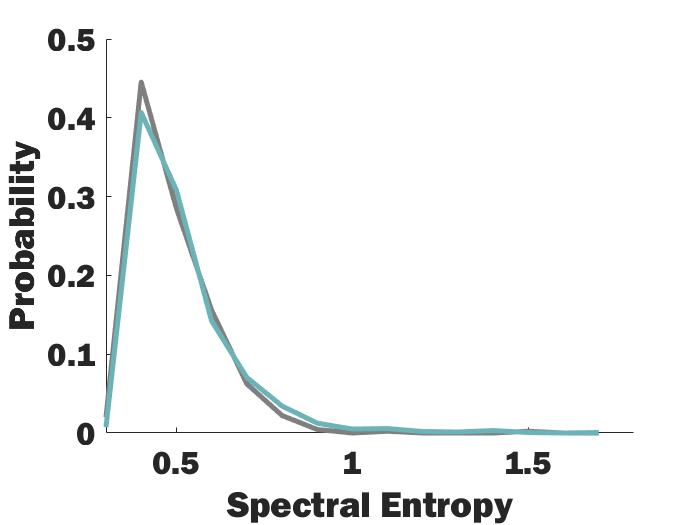

% Plot just pitch histogram
figure(124);clf; hold on
day68 = spectral_entropy(1:449);
day73 = spectral_entropy(450:end);
% day88_low = day88(day88 < 2580);
% day88_hi = day88(day88 >= 2580);
xlo = 0.3;
xhi = 1.8;

[n1,bins1] = histcounts(day68,xlo:0.1:xhi);
[n2,bins2] = histcounts(day73,xlo:0.1:xhi);
% [n3,bins3] = histcounts(day88_low,2200:50:3000);
% [n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#7F7F7F';
p1.LineWidth = 3;
p2 = plot(bins2(1:end-1),n2/length(day73));
p2.Color = '#6BB3B6';
p2.LineWidth = 3;
% p3=plot(bins4(1:end-1),n4/length(day88_hi));
% p3.Color = '#EA63C2';
% p3.LineWidth = 3;

xlim([xlo xhi])
xlabel(['Spectral Entropy'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

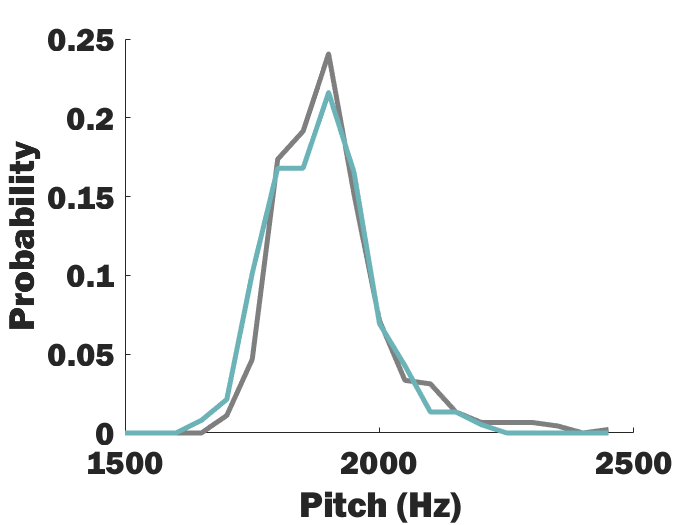

% Plot just pitch histogram
figure(124);clf; hold on
day68 = pitch(1:449);
day73 = pitch(450:end);
% day88_low = day88(day88 < 2580);
% day88_hi = day88(day88 >= 2580);

[n1,bins1] = histcounts(day68,1500:50:2500);
[n2,bins2] = histcounts(day73,1500:50:2500);
% [n3,bins3] = histcounts(day88_low,2200:50:3000);
% [n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#7F7F7F';
p1.LineWidth = 3;
p2 = plot(bins2(1:end-1),n2/length(day73));
p2.Color = '#6BB3B6';
p2.LineWidth = 3;
% p3=plot(bins4(1:end-1),n4/length(day88_hi));
% p3.Color = '#EA63C2';
% p3.LineWidth = 3;

xlim([1500 2500])
xlabel(['Pitch (Hz)'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)

set(gcf,'Visible','On')


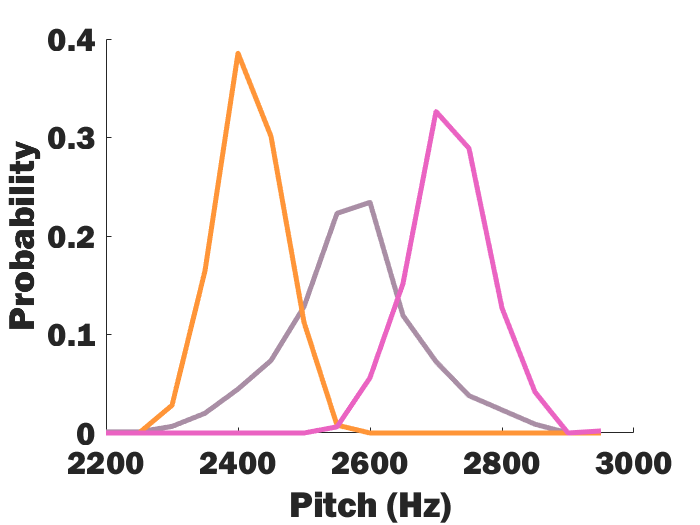

% Plot just pitch histogram

figure(123);clf; hold on
day68 = pitch(1:897);
day88 = pitch(897:end);
day88_low = day88(day88 < 2580);
day88_hi = day88(day88 >= 2580);

[n1,bins1] = histcounts(day68,2200:50:3000);
[n2,bins2] = histcounts(day88,2200:50:3000);
[n3,bins3] = histcounts(day88_low,2200:50:3000);
[n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#A98EA5';
p1.LineWidth = 3;
p2 = plot(bins3(1:end-1),n3/length(day88_low));
p2.Color = '#FF9538';
p2.LineWidth = 3;
p3=plot(bins4(1:end-1),n4/length(day88_hi));
p3.Color = '#EA63C2';
p3.LineWidth = 3;

xlim([2200 3000])
xlabel(['Pitch (Hz)'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)

set(gcf,'Visible','On')


## STEP 3: Quantify Acoustics with PCA

For a given syllable, create a matrix of the spectrogram power for each frequency bin (columns) for each syllable trial (row). 

bird = 'br177yw112';
syls = 'bk';
days = [62 68 73 88];
dims = 'acparams'; % dimensions to analyze: acparams, spec_slice, or spec_allfreqs;

% Collate matrices for all days
allSylDays = [];
groupID = [];
for s = 1:length(syls)
    allDays = [];
    for d = 1:length(days)
        try
        % load acoustic data for syllable for day(d) and store in allAcoustics
        [~,~,~,folder,recdate] = raster_params(bird,days(d));
        cd(folder)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl);
    
        % Create the matrix with the dimension type of choice
        switch dims
            case 'acparams'
                datamatrix = syl_sum(:,[5,12:15]); datamatrix = table2array(datamatrix); 
%                 datamatrix(:,3) = log(syl_sum.amp_sm_window);
                cats = syl_sum.Properties.VariableNames([5,12:15]); 
            case 'spec_slice'
                datamatrix = P1_save;
                cats = string(1:1:size(datamatrix,2));
            case 'spec_allfreqs'
                datamatrix = P1_save_allfreqs; %each row is spectrogram slice's power for 1 syllable
                cats = string(1:1:size(datamatrix,2));
        end
        
        groupId = repmat([num2str(days(d)) syls(s)],size(fn_syl,1),1);
        allDays = vertcat(allDays,datamatrix);
        catch
            message = ['failed for: ' num2str(days(d)) ' -syl ' syls(s)];
            disp(message)
        end
    end

    allSylDays = vertcat(allSylDays,allDays);
end

figure(); boxplot(zscore(allSylDays),'Orientation','horizontal','Labels',cats)   
title(sprintf('syllable %s, z-scored acoustics across days: %s',syls,num2str(days)))

% run_pca(zscore(allDays),cats,0)
run_pca(allSylDays,cats,1)


function run_pca(matrix,cats,weighting)

%Check Pairwise Correlation between columns
C = corr(matrix,matrix)

% Compute PCs
    % coeff = eigenvectors of the covariance matrix
    % score = data * eigenvectors (i.e. projections on the PC vector space)
    % latent = eigenvalues of the covariance matrix (i.e. the variances of the
    % vectors)
    % explained = % variance explained by each PC
% w = 1./var(allDays); %use the inverse variances of the data as weights
if weighting == 1
    [wcoeff, score, latent, tsquared, explained] = pca(matrix,...
        'VariableWeights','variance');

    % Take the coff vectors of the first 3 PCs. 
    c3 = wcoeff(:,1:3); %these are weighted, therefore not orthonormal

    % Transform coefficients so that they are orthonormal
    coeff = diag(std(matrix))\wcoeff;
    
    % Check that transformed coefficients are orthonormal
    I = coeff'*coeff;
    I(1:3,1:3)

elseif weighting == 0
    [coeff, score, latent, tsquared, explained] = pca(matrix);
    I = coeff'*coeff;
    I(1:3,1:3)
end

% Plot component scores
figure
plot(score(:,1),score(:,2),'+','Color','red'); 
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
pts = gname; %plot outliers
getpts = get(pts,{'string'});
points = cellfun(@str2double,getpts,'UniformOutput',false);
points = cat(1,points{:})



% Component Variances
latent

% Make Scree plot
figure; pareto(explained);
xlabel('PC')
ylabel('Variance Explained (%)')

% Find the most extreme points using Hotelling's T-squared Statistic
[st2, index] = sort(tsquared,'descend');
extreme_idx = index(1)

% Biplot: Visualizes both the orthonormal PC coeffs for each variable and the PC
% scores for each data point
figure %2 PCs
biplot(coeff(:,1:2),'Scores',score(:,1:2),'Varlabels',cats)

figure %3 PCs
biplot(coeff(:,1:3),'Scores',score(:,1:3),'VarLabels',cats)

end

function zscore_pca(matrix)
    % Do the PCA
    % coeff = eigenvectors of the covariance matrix
    % score = data * eigenvectors (i.e. projections on the PC vector space)
    % latent = eigenvalues of the covariance matrix (i.e. the variances of the
    % vectors)
    % explained = % variance explained by each PC
    
    [coeff,score,latent,tsquared,explained,mu] = pca(matrix) ;
    
    % Visualize the data representation in the space of the first three principal components.
    figure; scatter3(score(:,1),score(:,2),score(:,3));
    axis equal
    xlabel('1st Principal Component')
    ylabel('2nd Principal Component')
    zlabel('3rd Principal Component')
    
    % Visualize both the orthonormal principal component coefficients for each variable and the principal component scores for each observation in a single plot.
    figure;biplot(coeff(:,1:2),'scores',score(:,1:2));
    
    % Visualize the cumulative contribution of each PC
%     figure;plot(cumsum(explained(1:3)),'-');
    figure; pareto(explained);
    xlabel('PC')
    ylabel('Variance Explained (%)')
end